# **Case Study Kepler's Third Law**

Between 1609 and 1619 Johannes Kepler formulated three laws, that describe the movement of the planets around the Sun:

- The orbit of a planet is an ellipse with the Sun at one of the two foci.

- A line segment joining a planet and the Sun sweeps out equal areas during equal intervals of time.

- The square of a planet's orbital period is proportional to the cube of the length of the semi-major axis of its orbit, e.g., $T^2 \propto a^3$.

In this livescript we will use MATLAB to investigate Kepler's Third Law by analysing planetary data of the type that Kepler would have had access to in 1619. The first step is to load the data, from a .csv file into a MATLAB table:


keplers_data = readtable("Keplers_data.csv") % load csv file

keplers_data = 6×3 table
      Planet         radius      period
    ___________    __________    ______

    {'Mercury'}    5.8194e+10     87.77
    {'Venus'  }    1.0831e+11     224.7
    {'Earth'  }     1.496e+11    365.25
    {'Mars'   }    2.2799e+11    686.95
    {'Jupiter'}    7.7792e+11    4332.6
    {'Saturn' }    1.4227e+12     10759


semi_major_a = keplers_data.radius;  % access the "radius" column of table
orbital_period = keplers_data.period;  % access the "period" column of table


To investigate the relationship between the semi major axis and the orbital period a first step could be to plot one against the other:

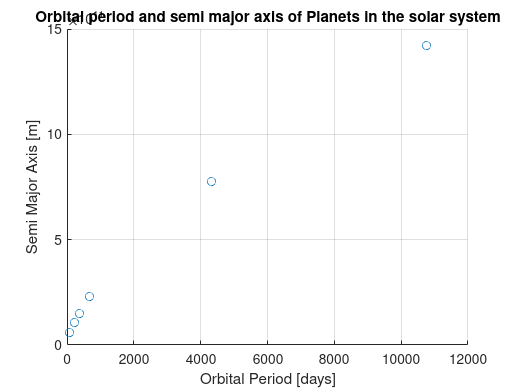

scatter(orbital_period, semi_major_a)
xlabel("Orbital Period [days]")
ylabel("Semi Major Axis [m]")
title("Orbital period and semi major axis of Planets in the solar system")
grid()

However, as Saturn and Jupiter have orbital periods that are significantly larger than the other planets known to Kepler at the time this squashes the data down into the bottom left corner and it is hard to see the relationship. Instead plotting the data on logarithmic axes may reveal a relationship:

loglog(orbital_period, semi_major_a, 'o') % plot points instead of a line
xlabel("Orbital Period [days]")
ylabel("Semi Major Axis [m]")
title("Orbital period and semi major axis of Planets in the solar system")
grid()

On a logarithmic plot it becomes apparent (straight line relationship) that the logarithm of the semi major axis is directly proportional to the logarithm orbital period. Calculating the line of ($y=mx+c $):

p = polyfit(log(orbital_period), log(semi_major_a), 1) % line of best fit

p =     0.6653   21.8075


m = p(1) % slope is stored as first element

m = 0.6653

c = p(2) % y-intercept is stored as second element

c = 21.8075

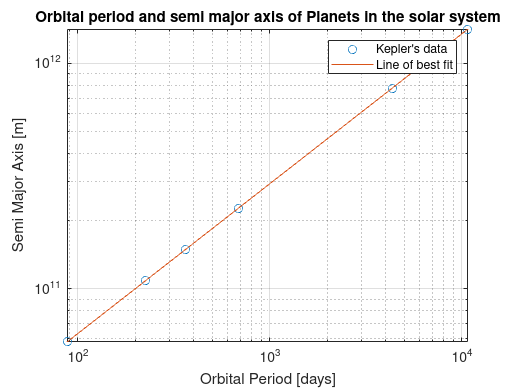


x_pts = [min(periods), max(periods)]; % range to plot line
line_pts = m.*log(x_pts) + c;        % evaluate line
hold on                              % add to existing plot
plot(x_pts, exp(line_pts))
legend(["Kepler's data", "Line of best fit"])

this line of best fit represents the relationship:

 
$$\log(a) = m\log(T)+c  \\
a = bT^m$$


 where $b = \exp(c) \approx 2.957\times 10 ^{10}  \text{ and } m \approx 2/3$. Cubing this equation gives

 
$$a^3 = b^3T^2\\$$


We can now use this relationship to make predictions about the semi Major axis of other planets:

predict_sm_axis = @(T) 2.957*(10^9)*T^(2/3) % anonymous function

predict_sm_axis = function_handle with value:
    @(T)2.957*(10^9)*T^(2/3)



modern_data = readtable("modern_data.csv") % load csv file

modern_data = 8×3 table
      Planet         radius      period
    ___________    __________    ______

    {'Mercury'}     5.791e+10    87.969
    {'Venus'  }    1.0821e+11     224.7
    {'Earth'  }     1.496e+11    365.26
    {'Mars'   }    2.2794e+11    686.98
    {'Jupiter'}    7.7842e+11    4332.8
    {'Saturn' }    1.4268e+12     10776
    {'Uranus' }     2.871e+12     30687
    {'Neptune'}    4.4983e+12     60190



% Predict semi major axis of Uranus:
period_uranus = table2array(modern_data(7, "period"))

period_uranus = 3.0687e+04

predict_sm_axis(period_uranus)

ans = 2.8984e+12


% Predict semi major axis of Neptune:
period_neptune = table2array(modern_data(8, "period"))

period_neptune = 6.0190e+04

predict_sm_axis(period_neptune)

ans = 4.5415e+12